addpath('../Functions/')

N = 3000;
g1 = [normrnd(0,1,N,1),normrnd(0,1,N,1)];
g2 = [normrnd(10,1,N,1),normrnd(10,1,N,1)];
g3 = [normrnd(-10,1,N,1),normrnd(10,1,N,1)];
g4 = [normrnd(0,1,N,1),normrnd(20,1,N,1)];
data = [g1;g2;g3;g4];
clear g1 g2 g3 g4

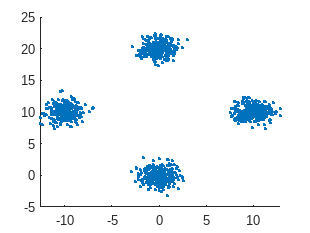

scatter(data(:,1),data(:,2),5,'filled')

D = squareform(pdist(data));
[~,ind] = sort(D);
k = 10;
for i=1:size(D, 1)
        D(i, ind((2 + k):end, i)) = 0;
end
A = D + D';
A(A~=0) = 1;
is_connected(A)

ans = logical
   0


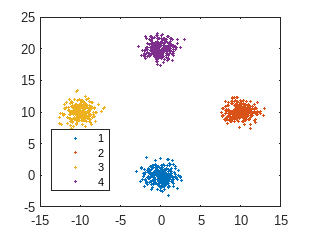

[comps,n]= find_comps(A);
gscatter(data(:,1),data(:,2),comps)

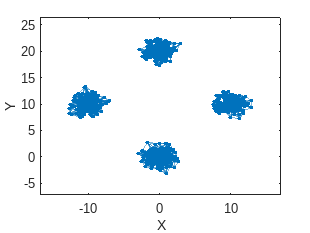


Ggraph = graph(A);
plt = plot(Ggraph, 'XData',data(:,1),'YData',data(:,2));

xlabel('X')
ylabel('Y')

Aprime = construct_graph_fast(data,5);

graph is not connected for  k = 5
connecting disconnected components


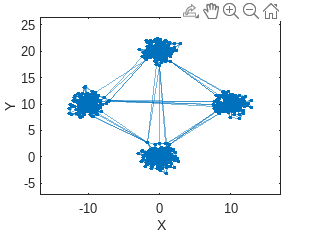

Ggraph = graph(Aprime);
plt = plot(Ggraph, 'XData',data(:,1),'YData',data(:,2));

xlabel('X')
ylabel('Y')

Aprime = construct_graph(data,true,true,5);

we have 4 connected components for k-1 = 299 in layer 1
Looking into component 1
Looking into component 2
Looking into component 3
Looking into component 4


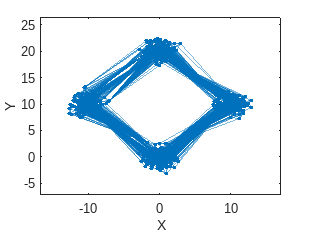

Ggraph = graph(Aprime);
plt = plot(Ggraph, 'XData',data(:,1),'YData',data(:,2));

xlabel('X')
ylabel('Y')